count = 0

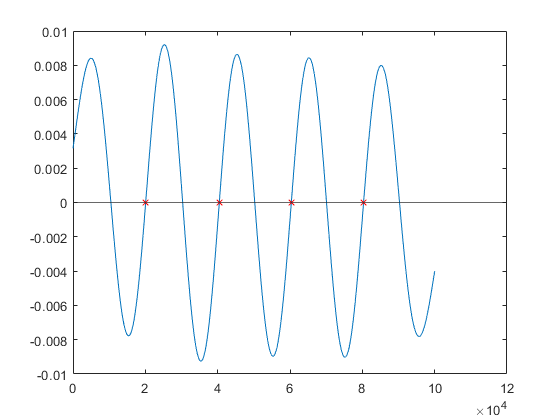

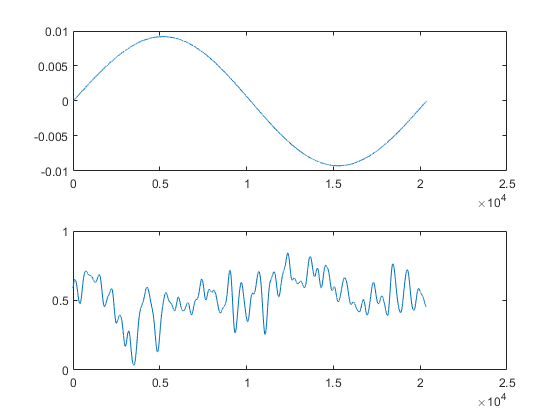

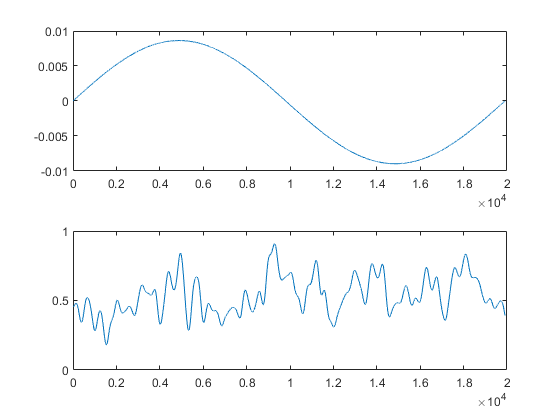

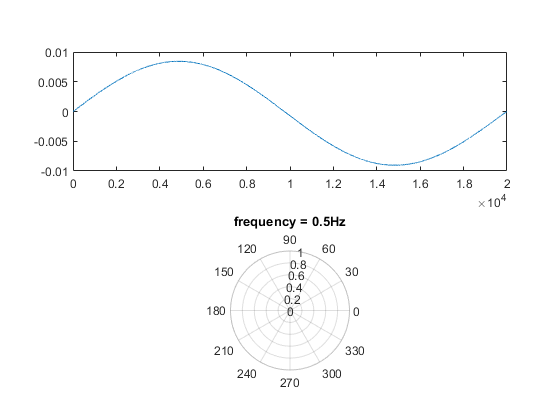

count = 0

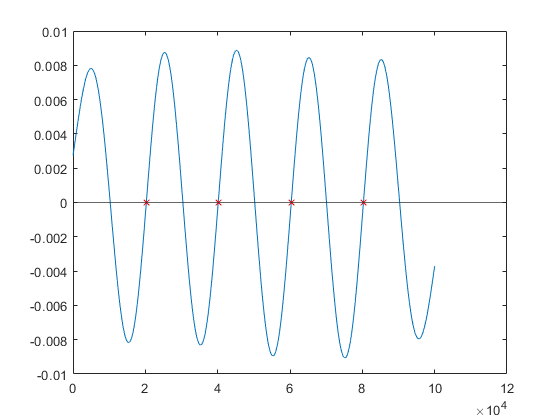

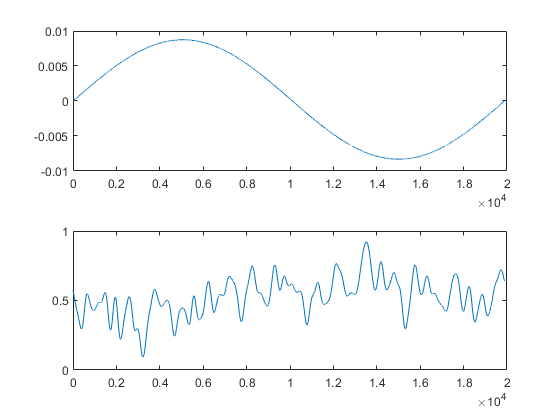

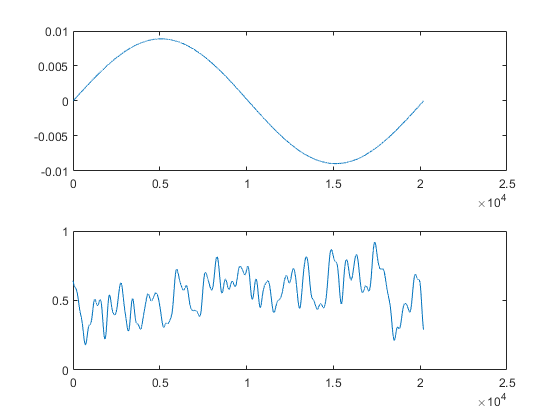

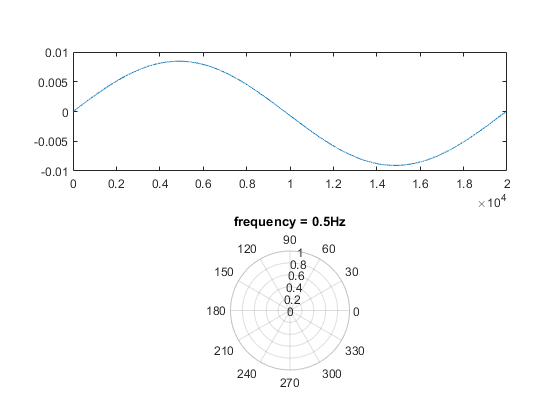

count = 0

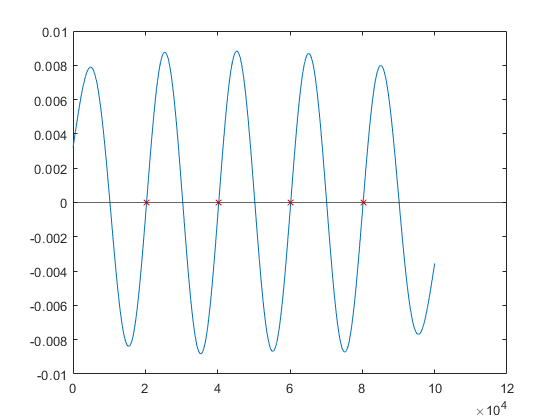

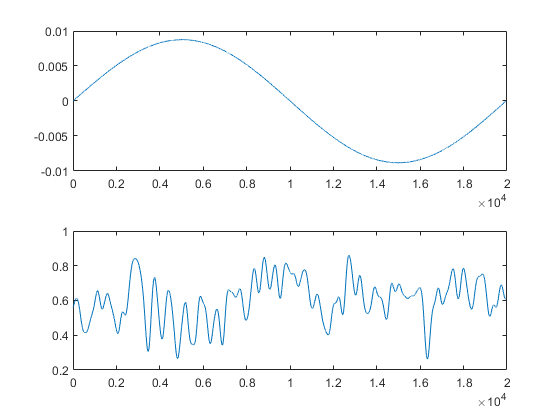

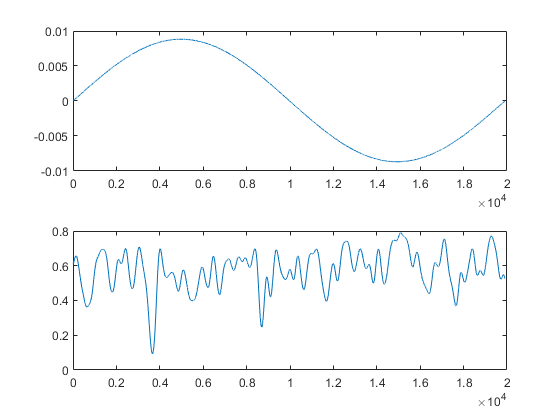

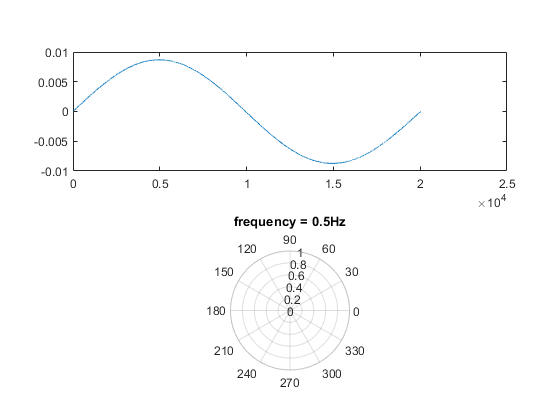

count = 0

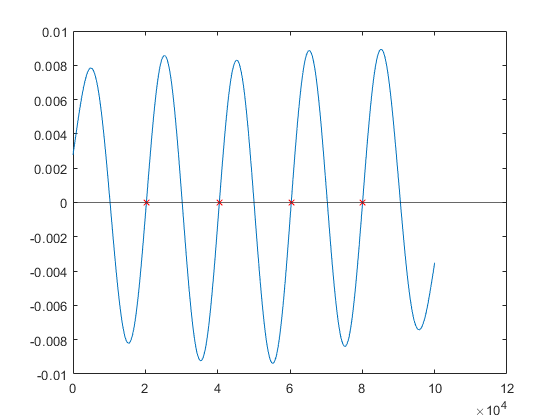

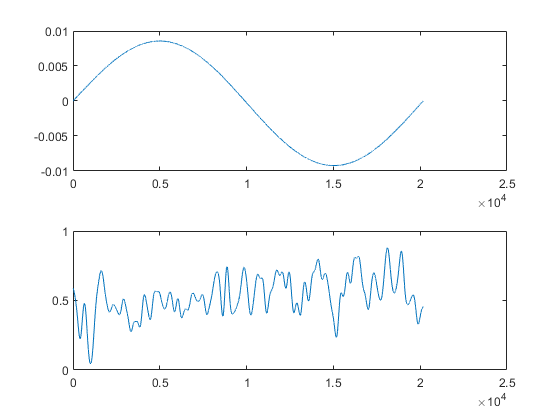

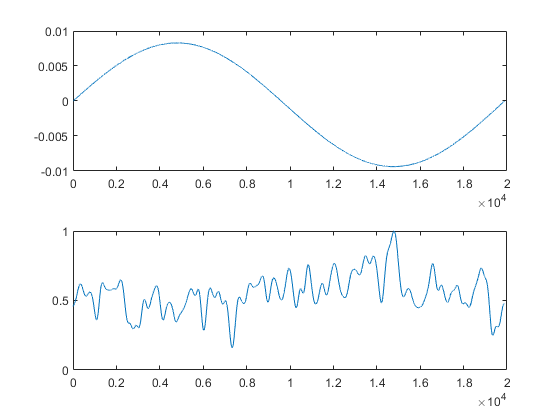

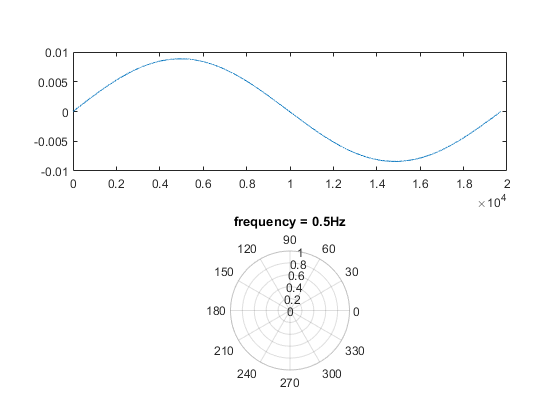

count = 0

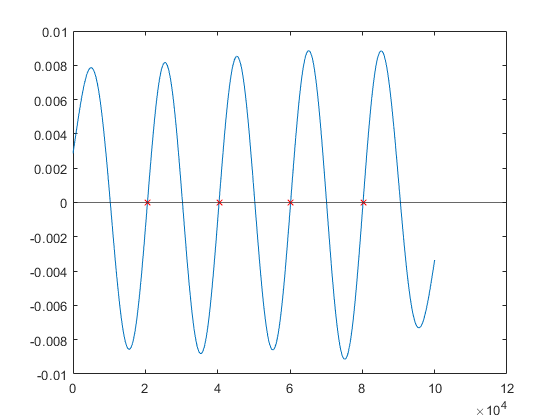

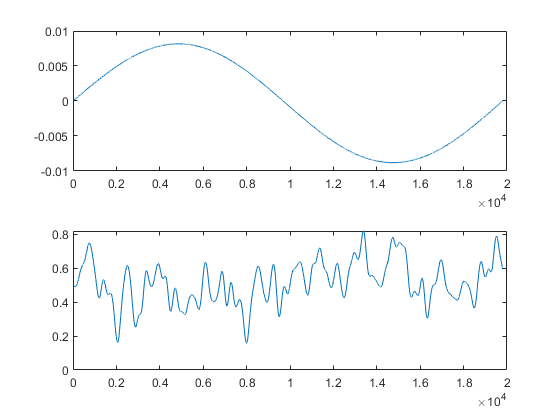

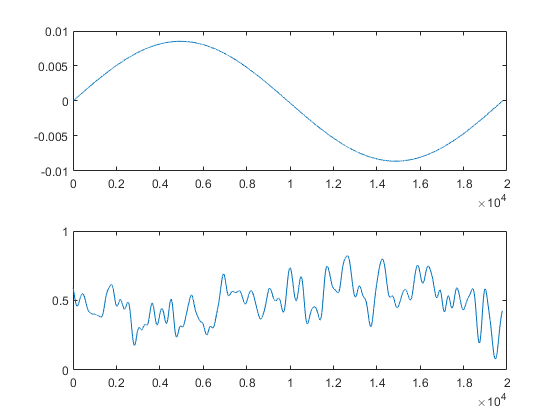

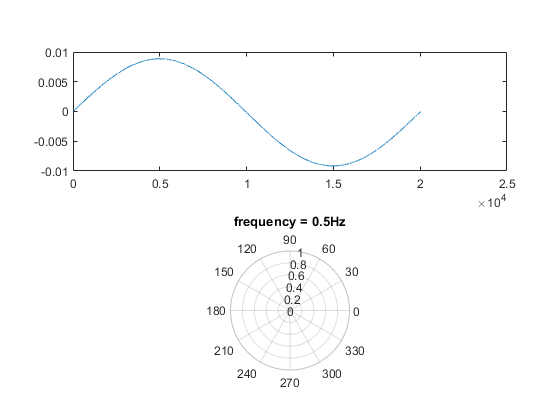

for protocol_num = 2
    resp = P(protocol_num).norm_gcfr(:, start_stim:stop_stim);
    stimulus = P(protocol_num).antennal_movement(:, start_stim:stop_stim);
    raster = P(protocol_num).raster(:,start_stim:stop_stim);
    
    
    zero_ind = find(raster==0);
    raster(zero_ind) = NaN;
    period = P(protocol_num).stim_period;
    
    stim = stimulus - mean(stimulus,2);
    
    [m,n] = size(stim);
    mean_positions = mean(stim, 2);
    % resp = resp - mean(resp,2);
    figure;
%         plot(stim(m,:)); hold on;
%         plot(raster(m,:).*4e-3, 'r|'); hold off;
    spike_phase_value = [];
    phase = [];
    gain = [];
    
    figure;
    for i = 1:m
        
        cos_theta = [];
        sin_theta = [];
        count = 0
        
        mean_pos  =mean_positions(i);
        
        locs = [];
        zc = [];
        for j = 2:n-1
            if (stim(i,j-1)<=mean_pos && stim(i,j)>=mean_pos && stim(i,j+1)>mean_pos)
                zc(j) = 1;
            end
        end
        [val,locs ]= find(zc==1);
        
        figure; plot(stim(i,:));hold on; plot(locs, stim(i,locs), 'rx'); yline(mean_pos); hold off;
        
        for k= 2:length(locs)
            
            
            stim_clips = stim(i, locs(k-1):locs(k)); figure(); subplot(2,1,1); plot(stim_clips);
            resp_clips = resp(i, locs(k-1):locs(k)); subplot(2,1,2); plot(resp_clips);
            raster_clips = raster(i, locs(k-1):locs(k));
            
            %         subplot(2,1,2); plot(raster_clips, 0, '|'  );
            
            if period > 0.2
                
                
                count = count + 1;
                coeff = corrcoef(stim_clips, resp_clips);
                corr_coeff(count)  = coeff(1,2);
                plot(period, coeff(count), '.'); hold on;
                
                
            elseif period <=0.2
                %             figure; plot(stim_clips);
                %             figure; plot(raster_clips);
                [~,stim_peak_ind] = max(stim_clips);
                ind = find(raster_clips == 1);
                if length(ind)>=1
                    count = count+1;
                    theta = (2*pi*ind(1)/fs)/period;
                    phase(count) = theta; %get_spike_phase(ind(1), fs, period);
                    
                    
                    cos_theta(count) = cos(theta);
                    sin_theta(count) = sin(theta);
                    
                    
                end
                
            end
        end
        sum(cos_theta);
        sum(sin_theta);
        vs(i) = (sqrt(((sum(cos_theta))^2)+((sum(sin_theta))^2)))/count;
        p(i) = mean(phase);
        polarscatter(p(i),vs(i), 100, '.'); hold on;
        title("frequency = " + 1/period + "Hz");
        % figure;
    end
    
end